clc; clear;

% General Solution
Vs = 0.5;
Vc_t = @(tau, t) Vs * (1 - exp(-t ./ tau));


% Import .csv data
A1 = readtable("RC_Circut_output_a1.csv")

A1 = 51×2 table
     t        Vc   
    ___    ________

      0           0
    0.1       0.025
    0.2     0.04875
    0.3    0.071313
    0.4    0.092747
    0.5     0.11311
    0.6     0.13245
    0.7     0.15083
    0.8     0.16829
    0.9     0.18488
      1     0.20063
    1.1      0.2156
    1.2     0.22982
    1.3     0.24333
    1.4     0.25616
    1.5     0.26835


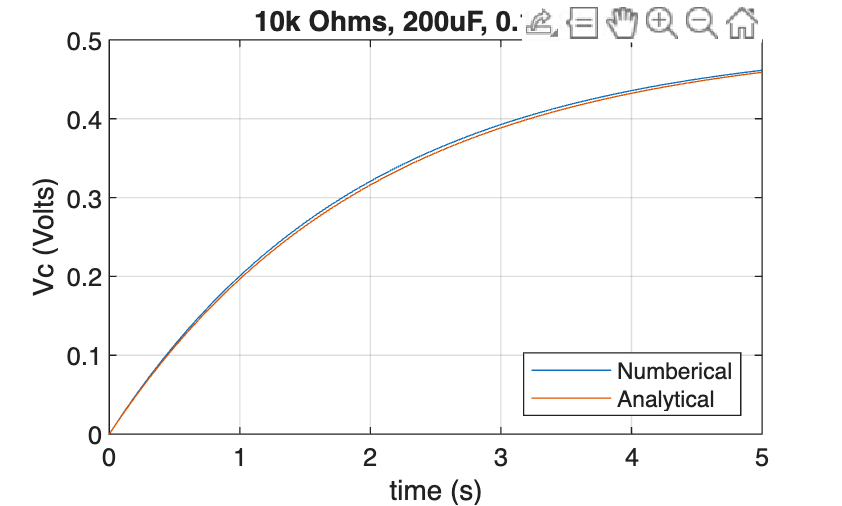

A2 = readtable("RC_Circut_output_a2.csv");
B1 = readtable("RC_Circut_output_b1.csv");
B2 = readtable("RC_Circut_output_b2.csv");

% Plot
grid on;
plot(A1.t, A1.Vc, A1.t, Vc_t(2, A1.t))
title("10k Ohms, 200uF, 0.1s Step");
xlabel("time (s)");
ylabel("Vc (Volts)");
legend ('Numberical', 'Analytical','Location','southeast');
grid on;

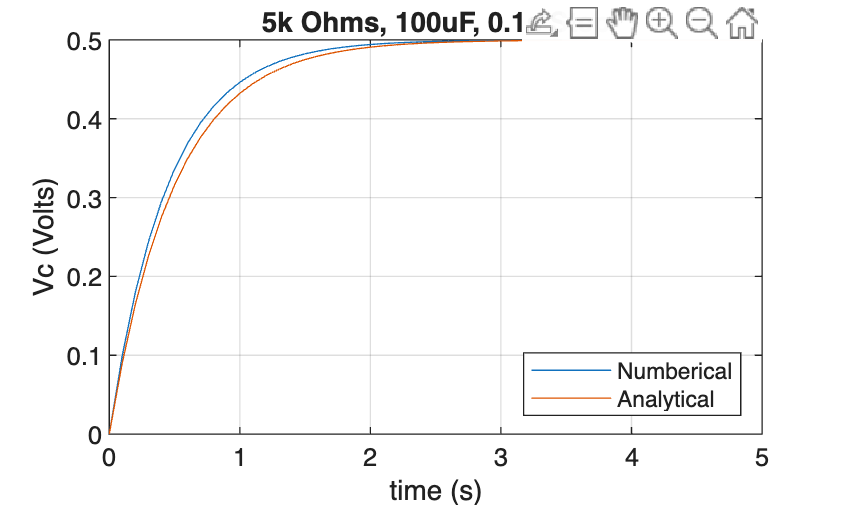



plot(A2.t, A2.Vc, A2.t, Vc_t(0.5, A2.t))
title("5k Ohms, 100uF, 0.1s Step");
xlabel("time (s)");
ylabel("Vc (Volts)");
legend ('Numberical', 'Analytical','Location','southeast');
grid on;

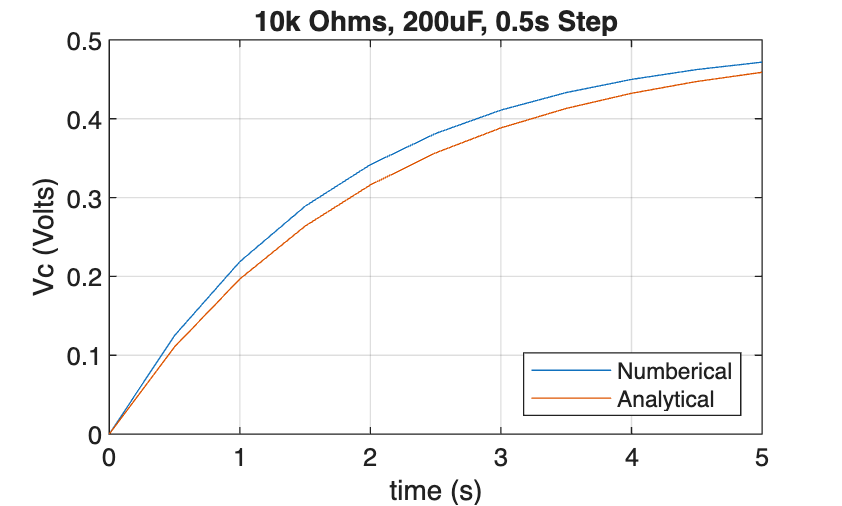



plot(B1.t, B1.Vc, B1.t, Vc_t(2, B1.t))
title("10k Ohms, 200uF, 0.5s Step");
xlabel("time (s)");
ylabel("Vc (Volts)")
legend ('Numberical', 'Analytical','Location','southeast');
grid on;



plot(B2.t, B2.Vc, B2.t, Vc_t(0.5, B2.t))
title("5k Ohms, 100uF, 0.5s Step");
xlabel("time (s)");
ylabel("Vc (Volts)");
legend ('Numberical', 'Analytical','Location','southeast');
grid on;

AnalyticalLine = findobj(gcf, "DisplayName", "Analytical")

AnalyticalLine =   Line (Analytical) with properties:

              Color: [0.8660 0.3290 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5]
              YData: [0 0.3161 0.4323 0.4751 0.4908 0.4966 0.4988 0.4995 0.4998 0.4999 0.5000]

  Show all properties


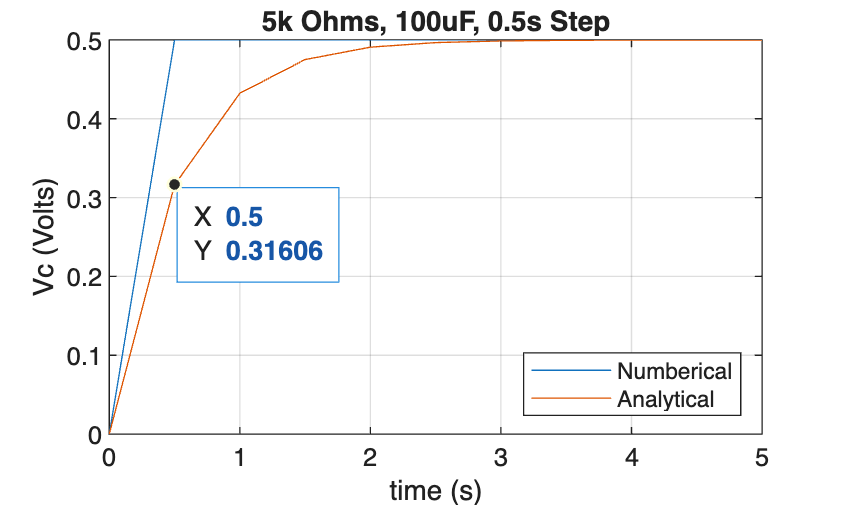

datatip(AnalyticalLine,0.5,0.3161,"Location","southeast");